# Light transduction, Figures 9-11

## Figure 9:  Spectral components

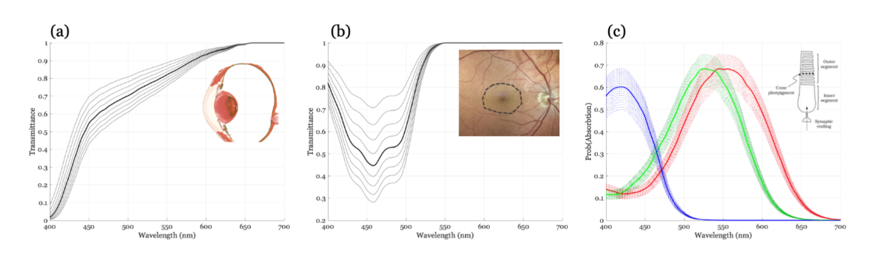

**Spectral properties** of visual system components that determine the input-referred quantum efficiency of the cones. (a) The crystalline lens dramatically reduces the fraction of short wavelength light transmitted to the retina. The optical density of the lens varies between people and with age. (b) The macular pigment is present in foveal, but not peripheral, regions of the retina. The pigment density in the fovea varies across people and with disease. (c) The optical density of the cone photopigment varies between people and across the retina. In all panels the dark solid curve is the standard and lighter curves are variations

### The lens

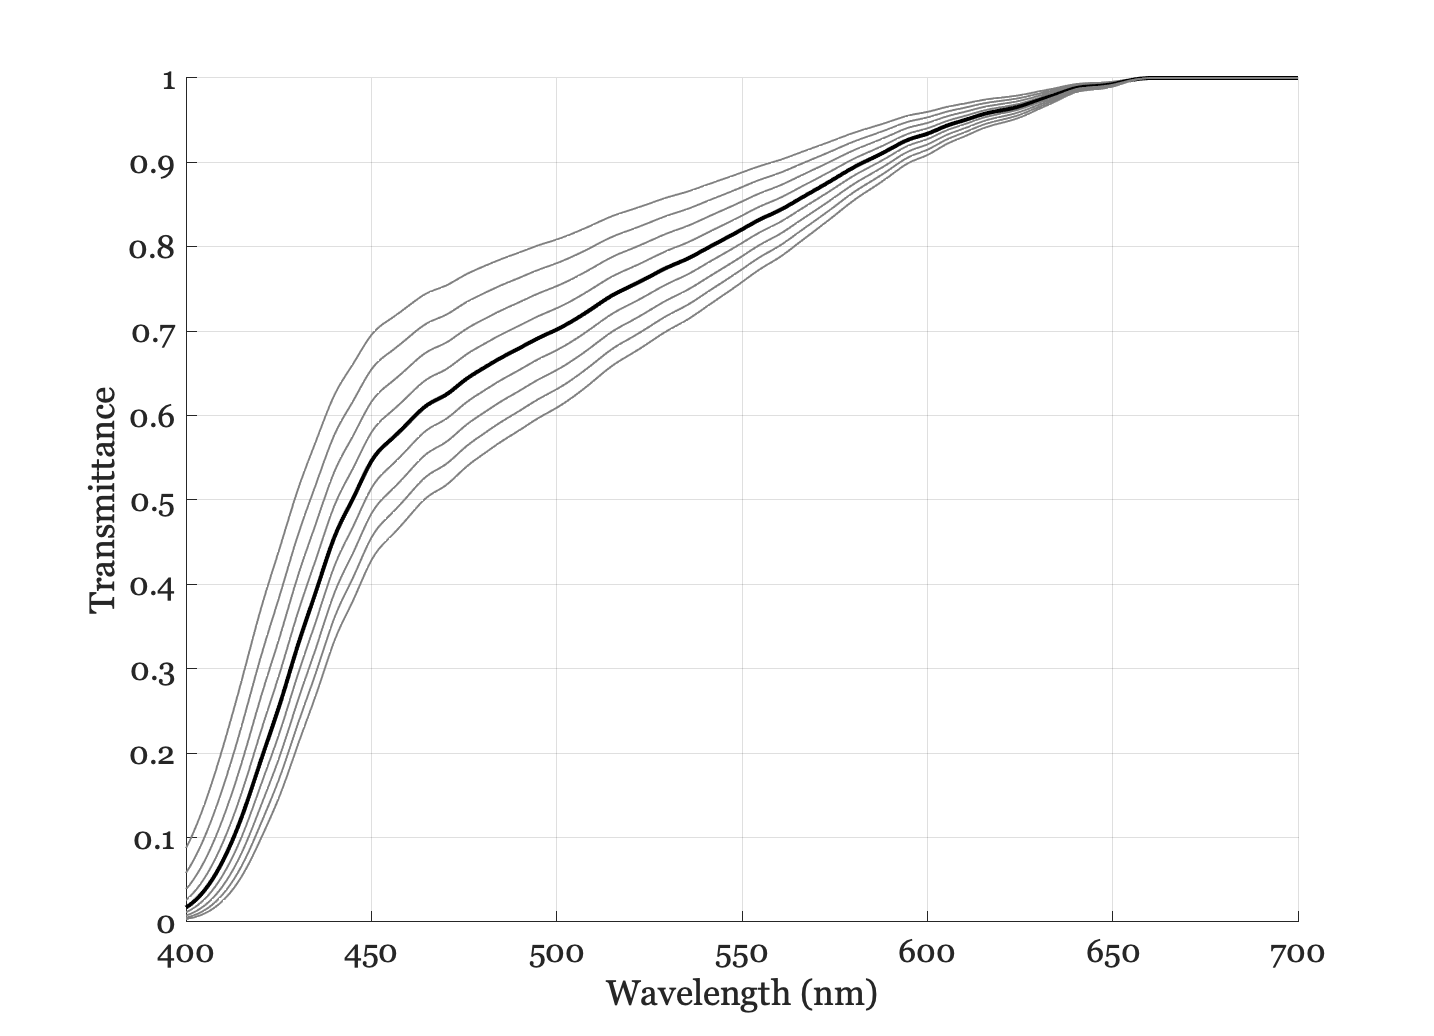

wave = 400:1:700;
thisLens = Lens;
thisLens.set('wave',wave);

% Default lens density
lensDensity = thisLens.density;

ieNewGraphWin;
hold on;

% Vary around the base
for dd = -0.4:0.1:0.4
    thisLens.density = lensDensity + dd;
    t = thisLens.transmittance;
    p = plot(wave,t,'color',[0.5 0.5 0.5]);
    if dd == 0
        p.LineWidth = 2; p.Color = 'k';
    end
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

### The macular pigment

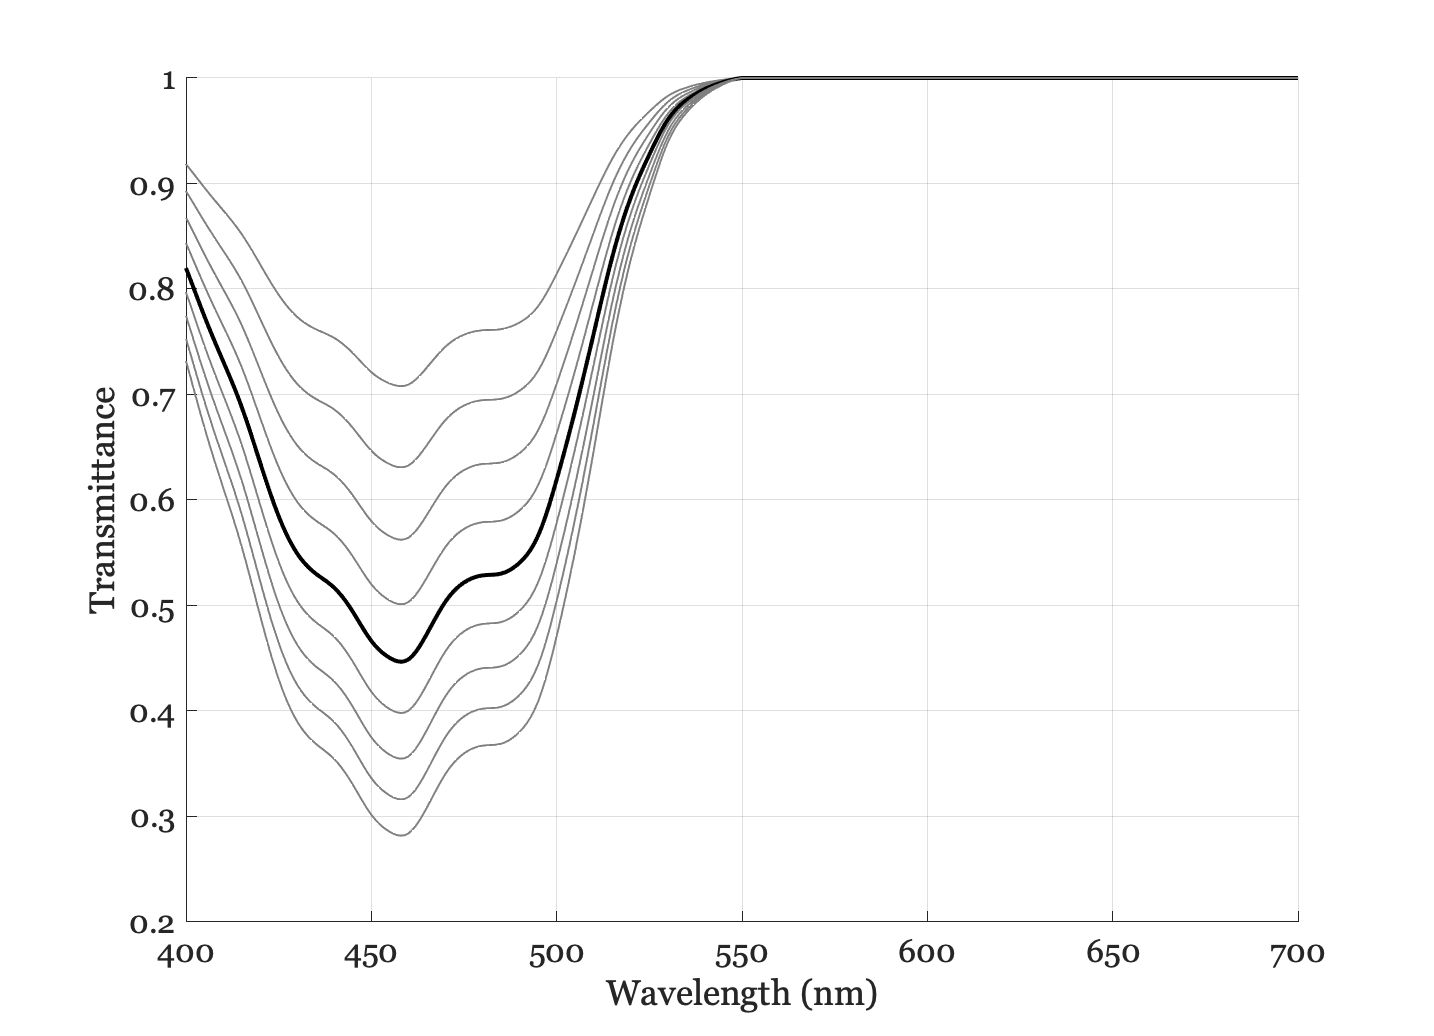

thisM = Macular;
thisM.wave = wave;

% Default
macularDensity = thisM.density;

ieNewGraphWin;
hold on;
% Vary around base
for dd = -0.2:0.05:0.2
    thisM.density = dd + macularDensity;
    t = thisM.transmittance;
    p = plot(wave,t,'color',[0.5 0.5 0.5]);
    if dd == 0
        p.LineWidth = 2; p.Color = 'k';
    end
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

### Cones pigment

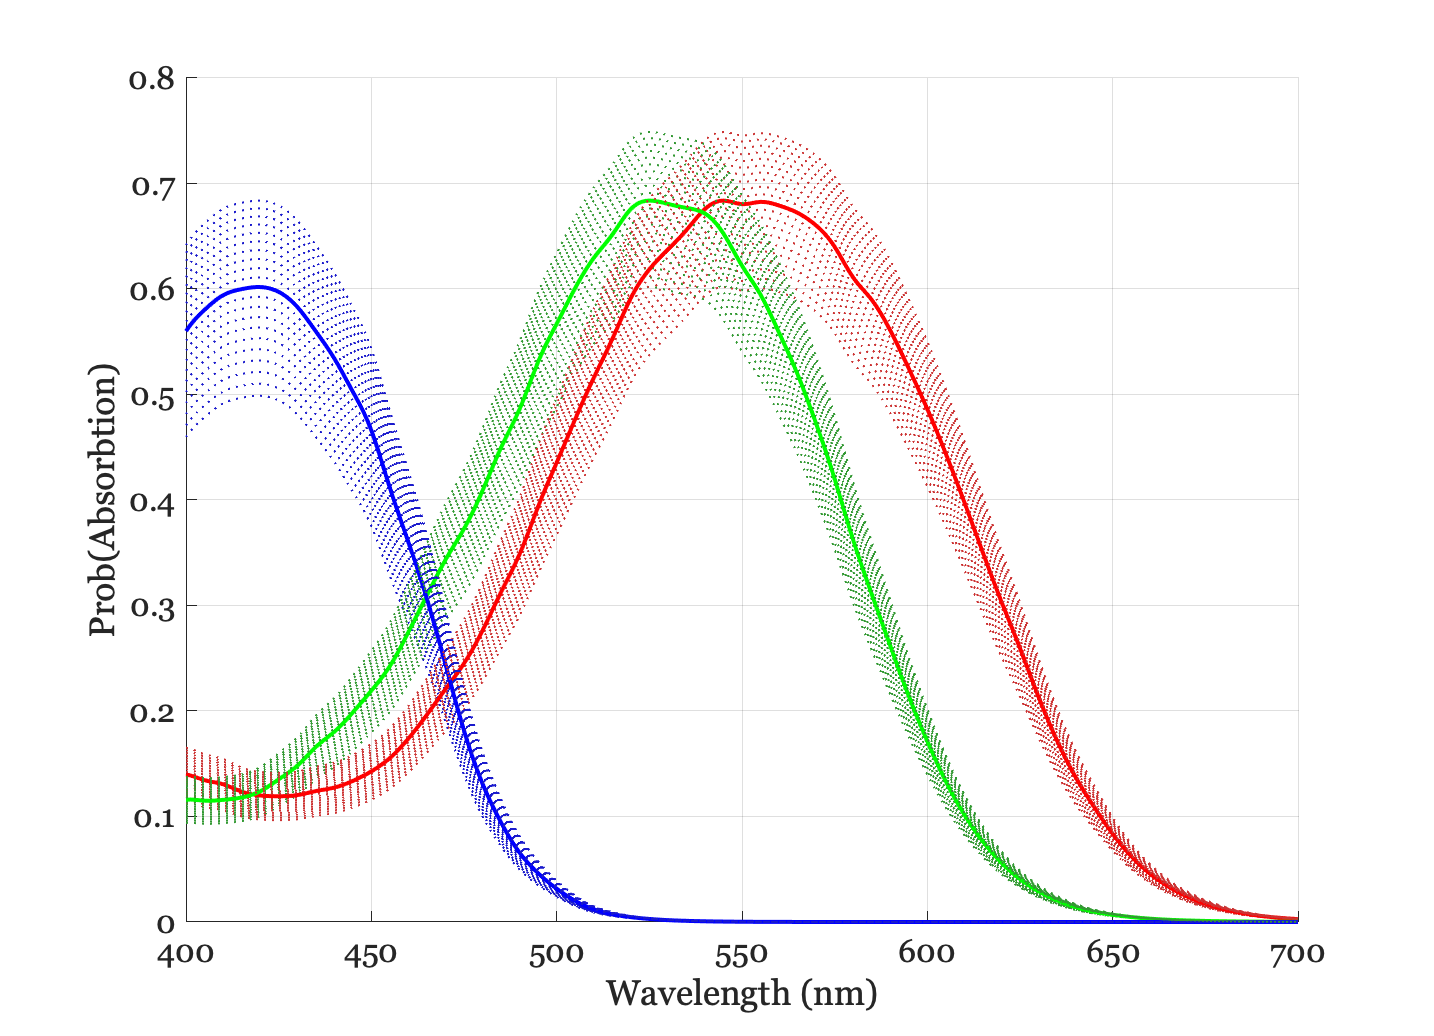

conePigments = photoPigment;
conePigments.wave = wave;

% Default
pigmentDensity = conePigments.opticalDensity;

ieNewGraphWin;
hold on;
thisColor = [0.8 0.2 0.2; 0.2 0.6 0.2; 0.1 0.1 0.8];
peakColor = {'r','g','b'};
% Vary around base
for dd=-0.1:0.01:0.1
    conePigments.opticalDensity = pigmentDensity + dd*ones(size(pigmentDensity));
    p = plot(conePigments.wave,conePigments.absorptance);
    for ii=1:3
        p(ii).Color = thisColor(ii,:); p(ii).LineStyle = ':';
    end
    
    if dd==0
        for ii=1:3
            p(ii).LineWidth = 2; p(ii).Color = peakColor{ii}; p(ii).LineStyle = '-';
        end
    end
end
grid on; xlabel('Wavelength (nm)'); ylabel('Prob(Absorbtion)');

### Fundamentals combined with varying lens, macular, and pigment

% Set up a mosaic with high wavelength sampling
cm = cMosaic;

min cone aperture diameter = 1.694712 microns


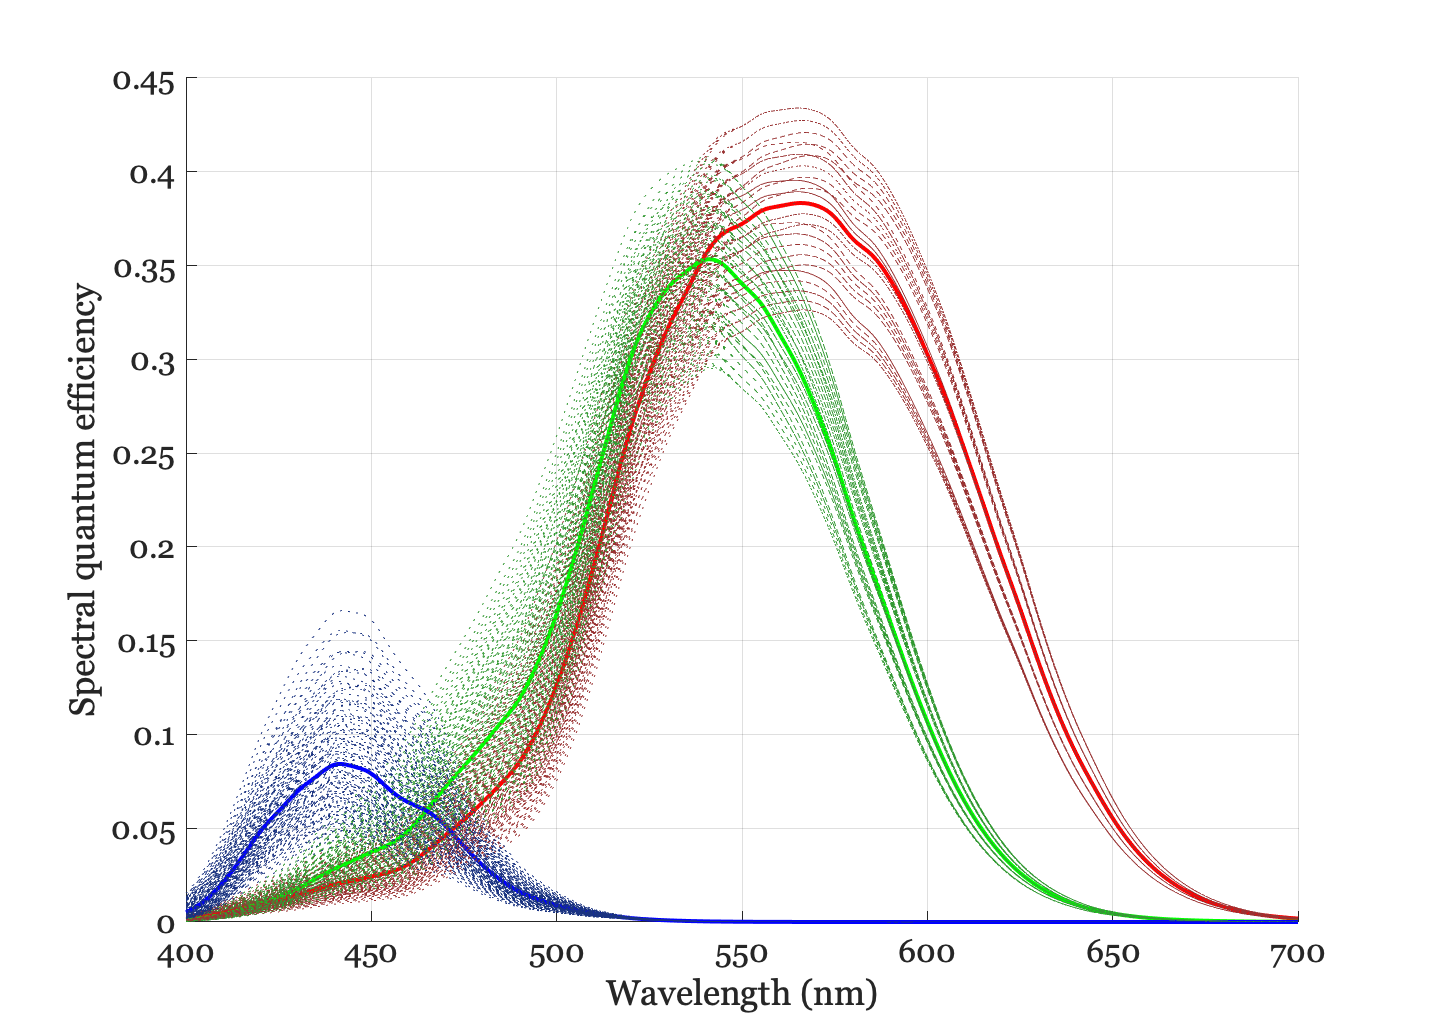

wave = 400:1:700;
cm.wave = wave;
thisLens.wave = wave;

% Make the plots
hdl = ieNewGraphWin;
hold on;
thisColor = [0.6 0.2 0.2; 0.2 0.6 0.2; 0.1 0.2 0.5];

for ll = -0.2:0.1:0.2
    thisLens.density = lensDensity + ll;
    for mm = -0.2:0.1:0.2
        cm.macular.density = macularDensity + mm;
        for pp = -0.1:0.05:0.1
            cm.pigment.opticalDensity = pigmentDensity + pp*ones(size(pigmentDensity));
            [~,fighdl] = cm.plot('spectral qe',[],'lens',thisLens,'hdl',hdl);
            p = fighdl.Children.Children;
            
            if ll==0 && mm == 0 && pp == 0
                % The standard.
                for ii=1:3
                    p(ii).LineWidth = 2;
                    p(ii).Color = peakColor{4-ii};                    
                end
            else
                for ii=1:3
                    p(ii).LineWidth = 0.5; 
                    p(ii).Color = thisColor(4-ii,:); p(ii).LineStyle = ':';
                end
            end
        end
    end
end

## Figure 10 - Cone fundamentals

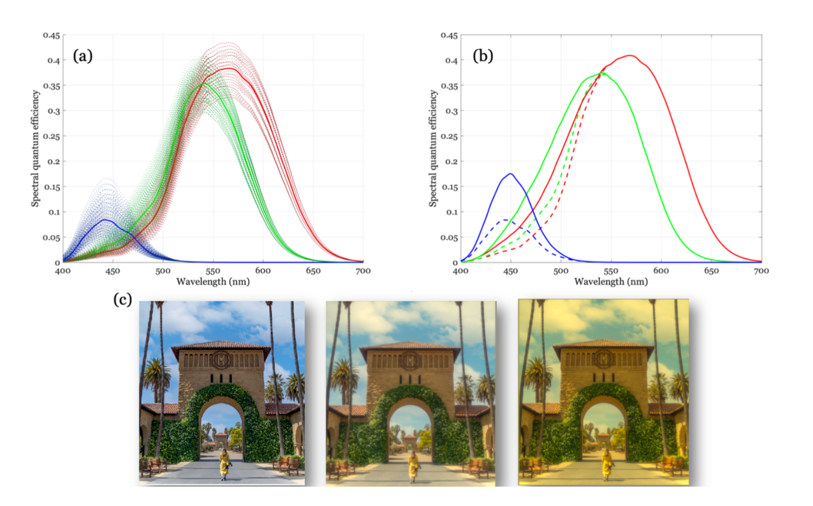

**Cone fundamentals. **The cone excitation calculations start with the stimulus (scene spectral radiance). The transmission through the lens and macular pigment combined with the cone absorptance form a spectral function called the cone fundamental. The fundamental is the input-referred spectral quantum efficiency of the cone. (a) The fundamental is defined using standard values (solid curves) for the lens, macular pigment and photopigment. There are significant variations (dotted curves) across the population, with the largest variation in the spectrum below 550 nm. (b) There is a reliable difference between the cone fundamentals near the fovea (dashed lines) and periphery because of the macular pigment (solid lines). (c) The three images give an impression of how the scene spectral radiance (left) is transformed as it passes through the lens (middle) and macular pigment (right). The ISETBio implementation includes lens factors as part of the retinal spectral irradiance (oi) computation; it includes macular pigment factors as part of the cone mosaic (cMosaic) computations.

## Fundamentals with and without macular pigment

hdl = ieNewGraphWin;
thisColor = [0.6 0.2 0.2; 0.2 0.6 0.2; 0.1 0.1 0.6];

cm.macular.density = 0.35;
cm.plot('spectral qe',[],'lens',thisLens,'hdl',hdl);

p = hdl.Children.Children;
for ii=1:3
    p(ii).LineWidth = 2;    
    p(ii).Color = peakColor{4-ii}; p(ii).LineStyle = '--';
end

hold on;
cm.macular.density = 0;
cm.plot('spectral qe',[],'lens',thisLens,'hdl',hdl);
p = hdl.Children.Children;

for ii=1:3
    p(ii).LineWidth = 2;
    p(ii).Color = peakColor{4-ii};
    p(ii).LineStyle = '-';
end

% legend({'Density 0.35','Density 0'});
scene = sceneFromFile('stanfordQuadEntryLowRes.png','rgb',100,...
    'reflectance-display',400:10:700);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


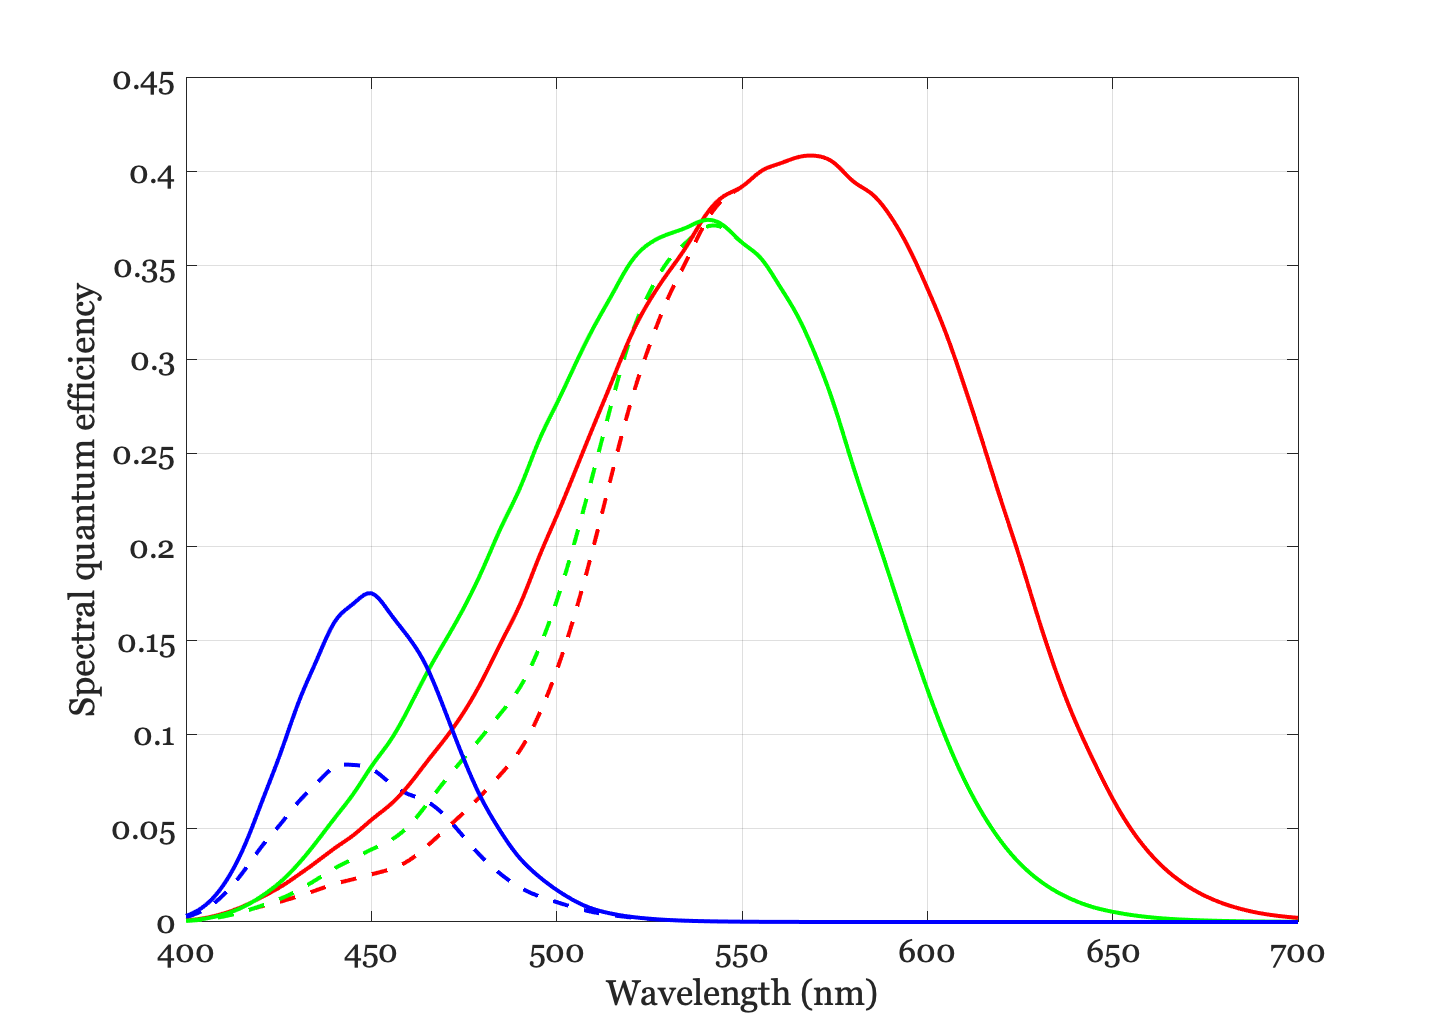

sceneWindow(scene);

oi = oiCreate;
oi = oiCompute(oi,scene);

% Just the lens
oiWindow(oi);

% The lens and add the macular pigment
thisM = Macular;
t = thisM.transmittance;
photons = oiGet(oi,'photons');
for ii=1:31
    photons(:,:,ii) = photons(:,:,ii)*t(ii);
end
oi = oiSet(oi,'photons',photons);
oiWindow(oi);

## Figure 11 - Cone sampling and aperture size

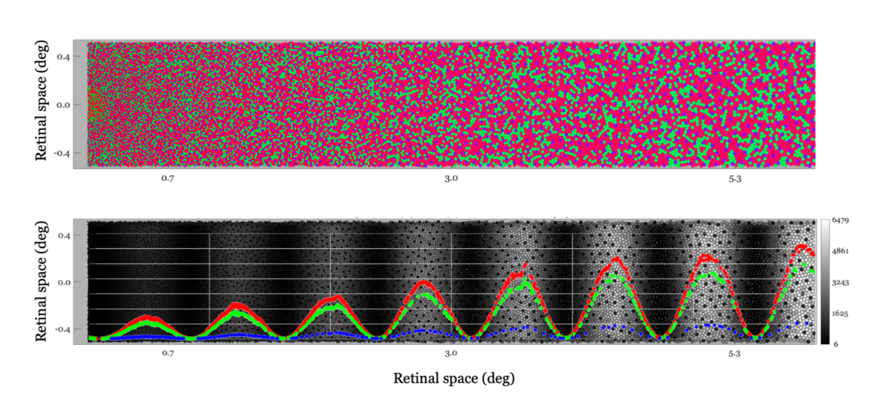

**Cone sampling and aperture size.** (Top) The spatial sampling density of the cone photoreceptors changes substantially decreasing from the fovea (left) to periphery (right). The image shows a narrow strip along the horizontal axis. As sampling density decreases, aperture size increases. Consequently for a constant irradiance pattern the number of excitations per cone increases. (Bottom) The gray scale image shows the estimated number excitations in the cone mosaic in response to a harmonic stimulus of constant contrast across the image. The colored curves show the mean number of excitations for each of the three cone types (scale bar at the right). 

### Cone mosaic

Create a strip along the horizontal axis.  The macular pigment varies along this strip.

cmP = cMosaicParams;
cmP.positionDegs = [3,0]; cmP.sizeDegs = [6 1];
cm = cMosaic(cmP);

min cone aperture diameter = 1.694712 microns


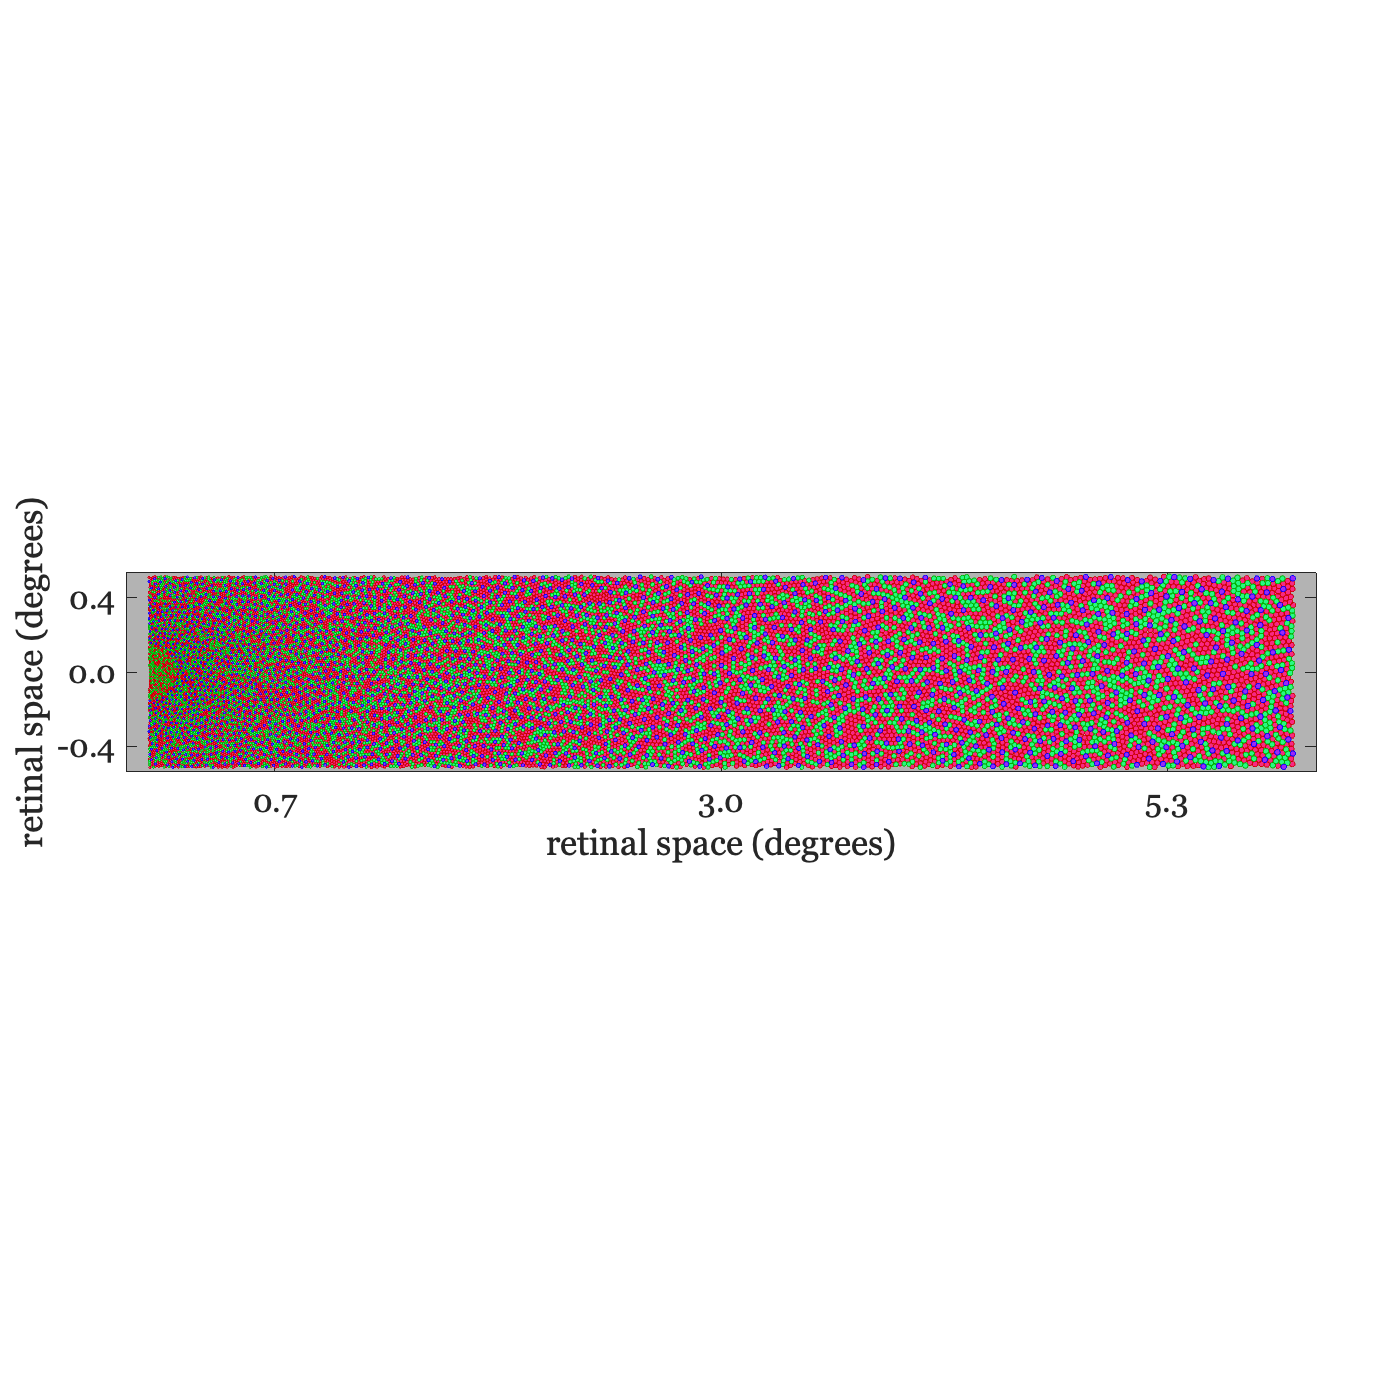

cm.visualize('plotTitle',false);

### Create a harmonic

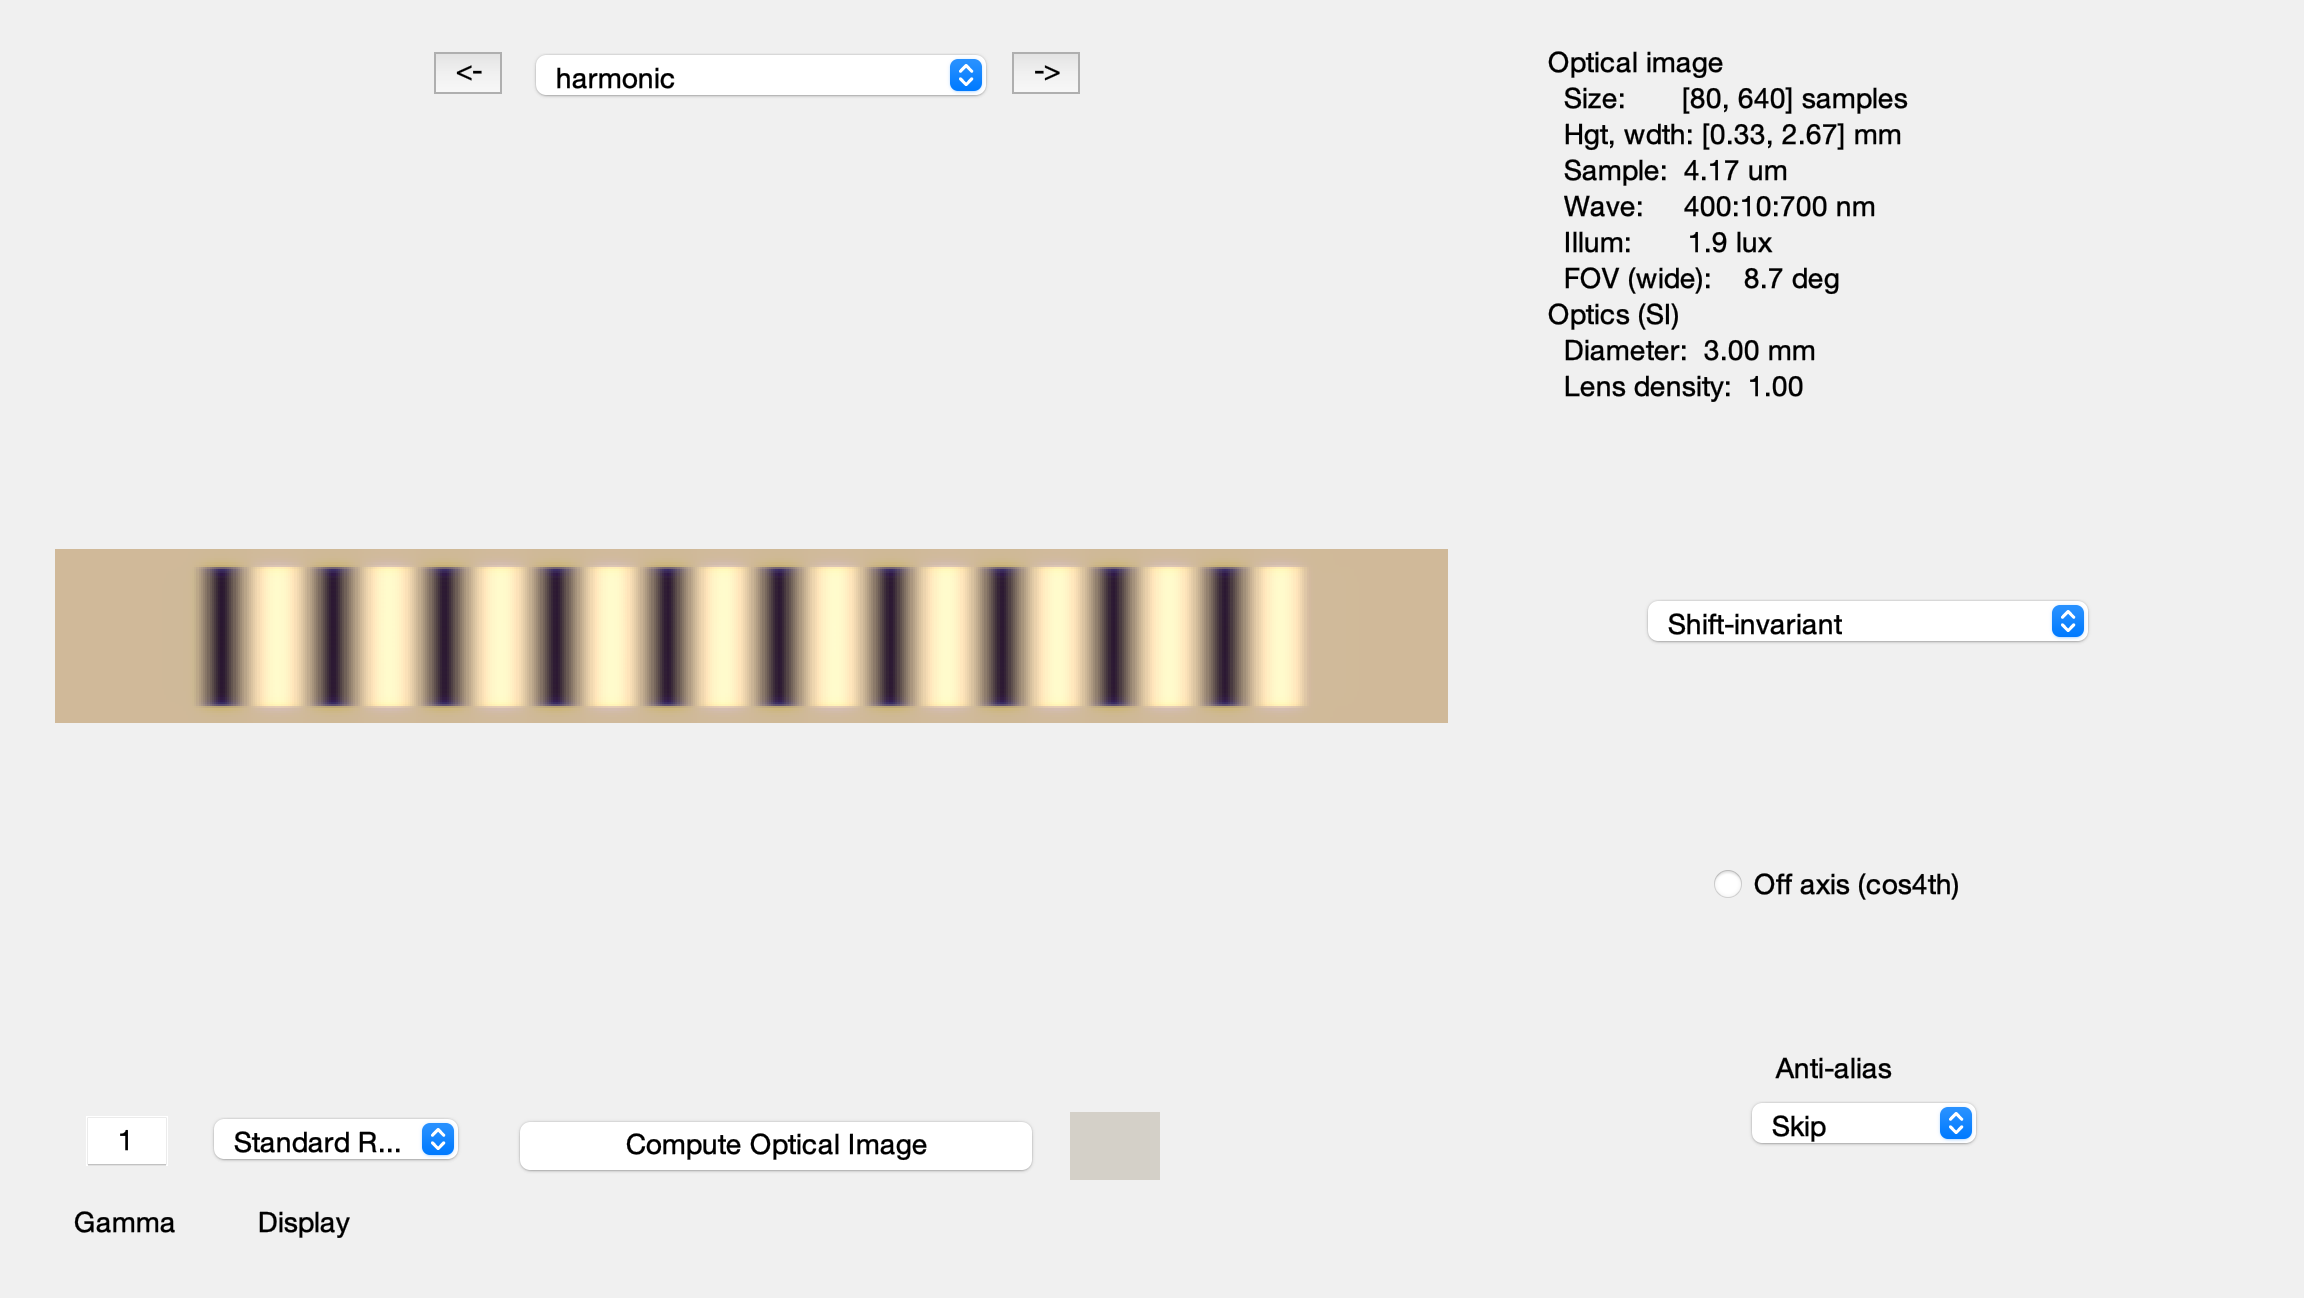

hP = harmonicP;
hP.col = 512;
hP.freq = 10;
scene = sceneCreate('harmonic',hP);
scene = sceneSet(scene,'fov',7);
oi = oiCreate('wvf human');
oi = oiCompute(oi,scene);
oiWindow(oi);

### Calculate the excitations

cm.integrationTime = 0.05;
allE = cm.compute(oi);

min cone aperture diameter = 1.716243 microns
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.


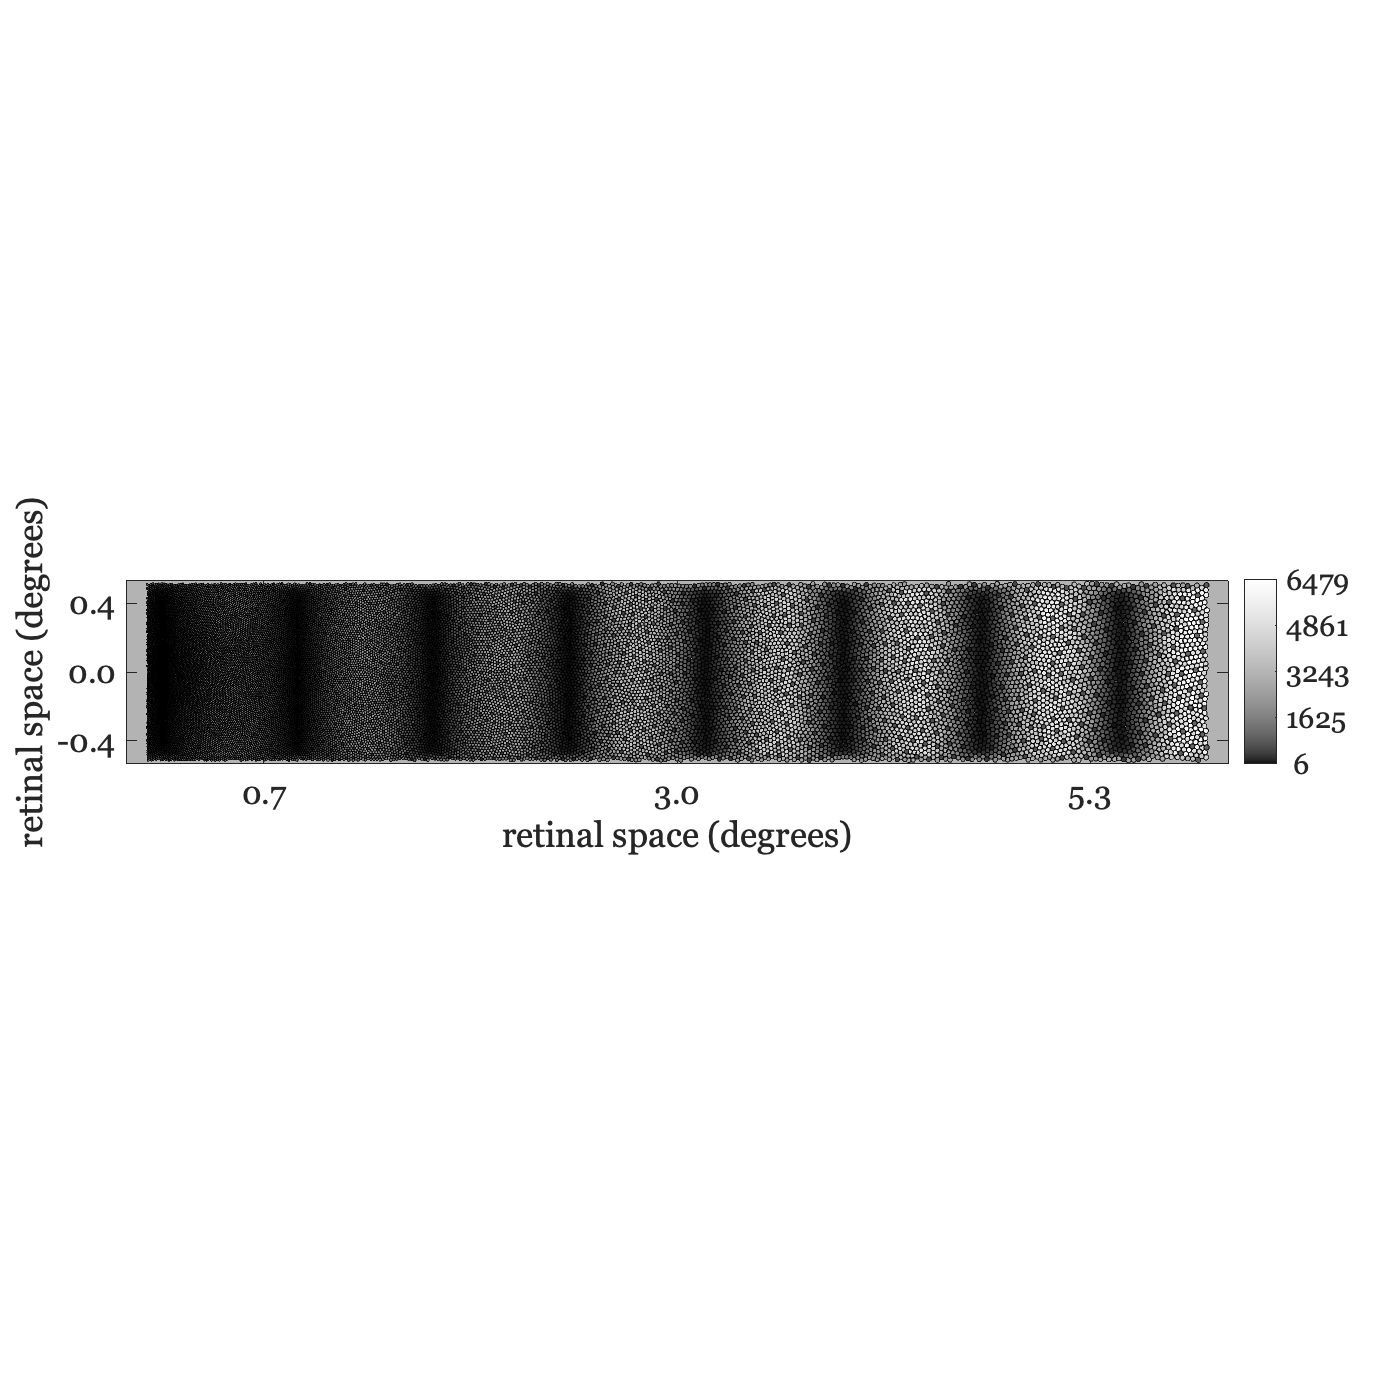


% Show one way
cm.plot('excitations',allE);
colormap(gray);
brighten(0.5);

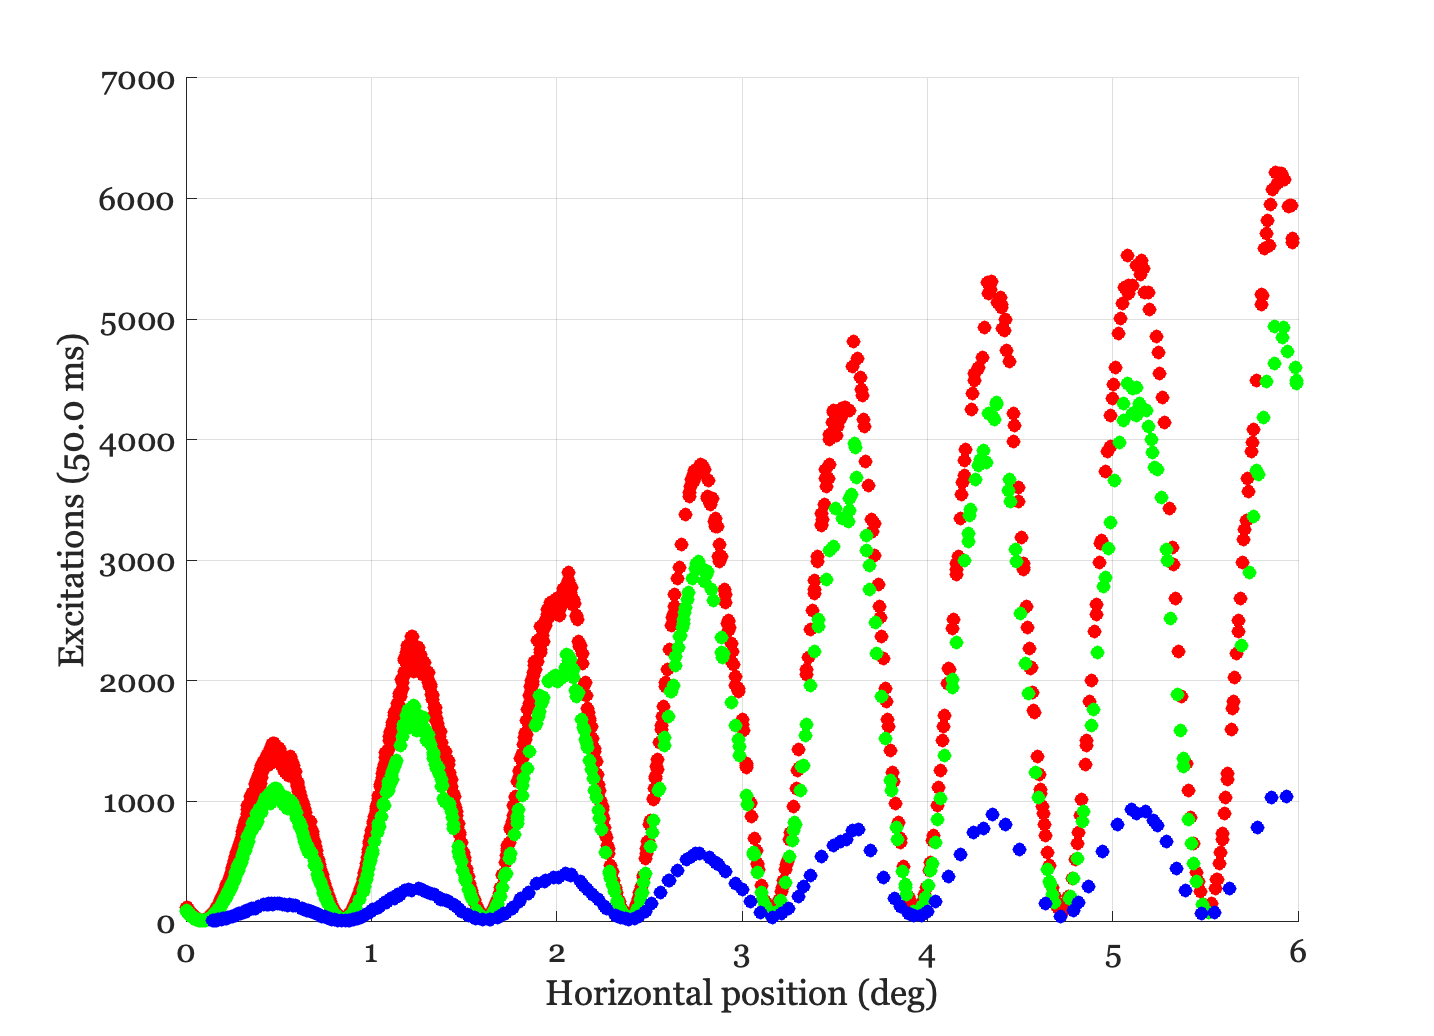

uData = cm.plot('excitations horizontal line',allE,'ydeg',0);

## A rough assessment of the total number of excitations per millimeter.

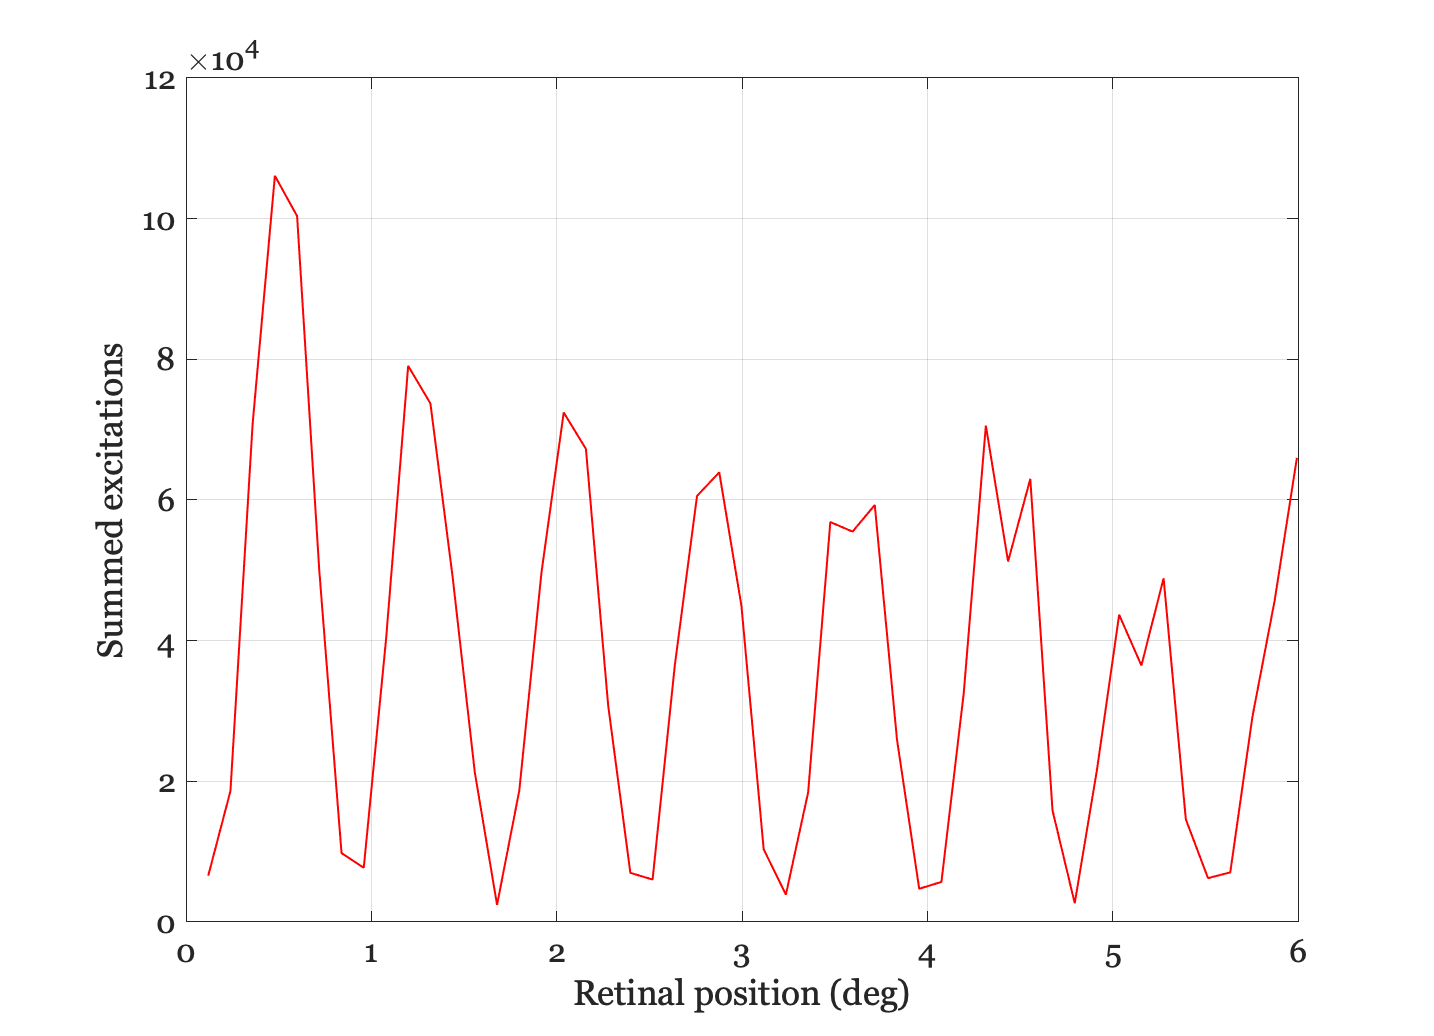

nRegions = 50;
pos  = uData.pos{1};
roiE = uData.roiE{1};
xRange = max(pos(:));
xStep = xRange/nRegions;
regionE = zeros(nRegions,1);
regionP = regionE;
excitations = squeeze(roiE);
for ii=1:nRegions
    l = pos(:,1) <= xStep*ii & pos(:,1) > xStep*(ii - 1);
    regionP(ii) = xStep*ii;
    regionE(ii) = sum(excitations(l));
end

ieNewGraphWin;
plot(regionP,regionE);
grid on;
xlabel('Retinal position (deg)'); ylabel('Summed excitations');